addpath(genpath('D:\OneDrive\OneDrive - UW-Madison\Sunduz\Betzel-method\GenLouvain-2.2.0'));
rep_dir = "D:\Data\SimulationData\settingSSoS\" + ...
    "n500-k10-p_in2btw4-p_out1btw1\" + ...
    "r_time0-time_horizon2-r_subject0-num_subjects8\" + ...
    "3";
samplesTotal = 100;

solving t=1
stage = 1/5, sample = 25/250
stage = 1/5, sample = 50/250
stage = 1/5, sample = 75/250
stage = 1/5, sample = 100/250
stage = 1/5, sample = 125/250
stage = 1/5, sample = 150/250
stage = 1/5, sample = 175/250
stage = 1/5, sample = 200/250
stage = 1/5, sample = 225/250
stage = 1/5, sample = 250/250
stage = 2/5, sample = 25/250
stage = 2/5, sample = 50/250
stage = 2/5, sample = 75/250
stage = 2/5, sample = 100/250
stage = 2/5, sample = 125/250
stage = 2/5, sample = 150/250
stage = 2/5, sample = 175/250
stage = 2/5, sample = 200/250
stage = 2/5, sample = 225/250
stage = 2/5, sample = 250/250
stage = 3/5, sample = 25/250
stage = 3/5, sample = 50/250
stage = 3/5, sample = 75/250
stage = 3/5, sample = 100/250
stage = 3/5, sample = 125/250
stage = 3/5, sample = 150/250
stage = 3/5, sample = 175/250
stage = 3/5, sample = 200/250
stage = 3/5, sample = 225/250
stage = 3/5, sample = 250/250


stage = 4/5, sample = 25/250
stage = 4/5, sample = 50/250
stage = 4/5, sample = 75/250
stage = 4/5, sample = 100/250
stage = 4/5, sample = 125/250
stage = 4/5, sample = 150/250
stage = 4/5, sample = 175/250
stage = 4/5, sample = 200/250
stage = 4/5, sample = 225/250
stage = 4/5, sample = 250/250
stage = 5/5, sample = 25/250
stage = 5/5, sample = 50/250
stage = 5/5, sample = 75/250
stage = 5/5, sample = 100/250
stage = 5/5, sample = 125/250
stage = 5/5, sample = 150/250
stage = 5/5, sample = 175/250
stage = 5/5, sample = 200/250
stage = 5/5, sample = 225/250
stage = 5/5, sample = 250/250
get initial estimate of boundaries: use time 706.01 s
sample 1/100, 0 try, elapsed time of 0.94 s
sample 2/100, 0 try, elapsed time of 1.54 s
sample 3/100, 0 try, elapsed time of 3.73 s
sample 4/100, 0 try, elapsed time of 4.54 s
sample 5/100, 0 try, elapsed time of 6.19 s
sample 6/100, 0 try, elapsed time of 7.88 s
sample 7/100, 0 try, elapsed time of 10.41 s
sample 8/100, 0 try, elapsed time of 11.39 

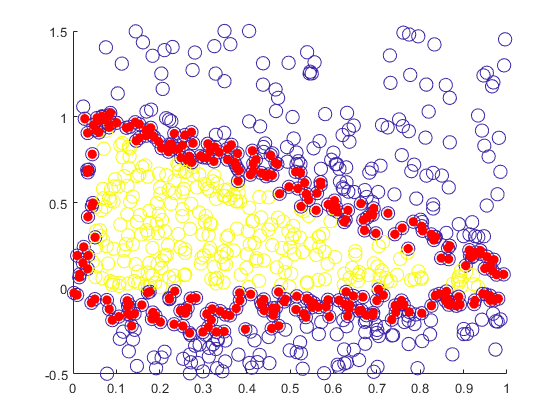

stage = 4/5, sample = 25/250
stage = 4/5, sample = 50/250


analyze_dvdbyT(rep_dir, samplesTotal);

aris_dbt = load(rep_dir+"\aris_dbt.mat").aris;
aris_ori = load(rep_dir+"\aris_ori.mat").aris;

aris1 = mean(aris_ori, [1,2]);
aris1 = reshape(aris1, samplesTotal, 1);

aris2 = mean(aris_dbt, [1,2]);
aris2 = reshape(aris2, samplesTotal, 1);

% mean(aris_st)

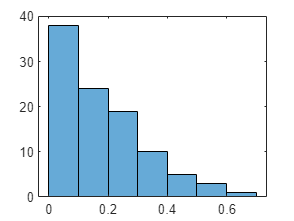

histogram(aris1);
histogram(aris2);

cur_dir = rep_dir;
adj = readNPY(cur_dir+"/"+"adj_mus_dynamic.npy");
z = readNPY(cur_dir+"/"+"z_mus_dynamic.npy");
B = permute(adj, [3,4,1,2]);
sizeB = size(B);
% A = reshape(B, sizeB(1),sizeB(2),sizeB(3)*sizeB(4),1);

S = sizeB(3);
T = sizeB(4);
zST = zeros(S, T,sizeB(1),samplesTotal);

for t = 1:T
    fprintf('solving t=%d\n', t);
    A = B(:,:,:,t);
    % [N,~,T] = size(A);  % number of nodes/layers
    C = cell(S,1);      % create cell array
    for i = 1:S         % populate array
        C{i} = A(:,:,i); 
    end

    %     set some parameters           
    gammarange = [double(min(A(:))), double(max(A(:)))]; % range of gamma values to consider
    omegarange = [-0.5,1.5];            % range of omega values to consider
    samplesPerStage = 250;              % number of samples per stage (ideally should be large) 250
    nstage = 5;                         % number of stages (ideally should be large) 5
    keep = 20;                          % number of nearest neighbors 20
    couplingtype = 'categorical';       % nature of interlayer coupling (could also be ordered)
    
    %     get initial estimate of boundaries
    tic
    [gbound,obound,~] = ...    % run boundary estimator
        fcn_get_bounds(C,gammarange,omegarange,samplesPerStage,nstage,keep,couplingtype);
    fprintf('get initial estimate of boundaries: use time %.2f s\n',toc);
    
    %     sample from within those boundaries
    [zS,G,O] = fcn_staged_multilayer(C,gbound,obound,samplesTotal,couplingtype);      
    
    zS = permute(zS, [2,1,3]);
    zST(:,t,:,:) = zS;
    % zS = reshape(zS, S, T,sizeB(1),samplesTotal);
end